% Given a speed, we want to find the propeller pitch to satisfy a specific
% pitch angle
clear all
clc
h = 100; % flight altitude
[~,~,~,rho] = atmosisa(h);
table_trim_no_redundant = readtable('trim_result_no_redundant.csv');
table_propeller_config = readtable('propeller_config.csv');
table_theta_preconfig = readtable('theta_preconfig.csv');

table_trim_redundant_prop = readtable('trim_result_redundant_prop.csv');

## build object

run init_build.m

## test program with zeros force theta_0_prop

Rotorcraft.DoubleRotorHelicopter.U         = 100;
Rotorcraft.DoubleRotorHelicopter.V         = 0;
Rotorcraft.DoubleRotorHelicopter.W         = 0;
Rotorcraft.DoubleRotorHelicopter.U_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.V_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.W_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.p         = 0;
Rotorcraft.DoubleRotorHelicopter.q         = 0;
Rotorcraft.DoubleRotorHelicopter.r         = 0;
Rotorcraft.DoubleRotorHelicopter.p_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.q_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.r_dot     = 0;

nearest_initial_no_redundant = table_trim_no_redundant{table_trim_no_redundant.U == fix(Rotorcraft.DoubleRotorHelicopter.U),2:10};
zero_force_theta_0_prop = table_propeller_config.zeros_force_theta_0(table_propeller_config.U == ceil(Rotorcraft.DoubleRotorHelicopter.U));

[theta,x_trim,Rotorcraft,power_total] = find_theta_given_prop(Rotorcraft, [zero_force_theta_0_prop, 0, 0], nearest_initial_no_redundant)

theta = -0.1965

x_trim =     0.3879   -0.0002    0.0001   -0.1313   -0.1965   -0.0000    1.3462    1.3491    0.6073


Rotorcraft = struct with fields:
    DoubleRotorHelicopter: [1×1 Helicopter]
               LowerRotor: [1×1 RotorFixed]
               UpperRotor: [1×1 RotorFixed]
                     Prop: [1×1 PropellerKevin]
                      Fus: [1×1 FuselageLynx]
                  HorStab: [1×1 HorizontalStabilizerNASA]
                  VerStab: [1×1 VerticalStabilizerNASA]


power_total = 6.2718e+05


info_dynamics(Rotorcraft)

                    X          Y          Z          L            M              N     
                  ______    ________    ______    _______    ___________    ___________

    LowerRotor    96.133      544.88    -31040    -508.53          11170          22403
    UpperRotor    108.23     -542.34    -31098     94.356          11014         -22404
    Propeller     389.25           0         0     414.17    -9.0469e-15    -9.0469e-15
    Fuslage       -11129    -0.68975    9221.6          0         -22184        0.78771
    HorStab            0           0         0          0              0              0
    VerStab            0           0         0          0              0     

## let's try set theta = 3deg when U = 0, and find the value of theta_0_prop

% consider the constrain of theta_0_prop, to avoid the thrust reverse
% use fmincon instead of fsolve
Rotorcraft.DoubleRotorHelicopter.U         = 50;
Rotorcraft.DoubleRotorHelicopter.V         = 0;
Rotorcraft.DoubleRotorHelicopter.W         = 0;
Rotorcraft.DoubleRotorHelicopter.U_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.V_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.W_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.p         = 0;
Rotorcraft.DoubleRotorHelicopter.q         = 0;
Rotorcraft.DoubleRotorHelicopter.r         = 0;
Rotorcraft.DoubleRotorHelicopter.p_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.q_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.r_dot     = 0;

nearest_initial_no_redundant = table_trim_no_redundant{table_trim_no_redundant.U == fix(Rotorcraft.DoubleRotorHelicopter.U),2:10};
zero_force_theta_0_prop = table_propeller_config.zeros_force_theta_0(table_propeller_config.U == ceil(Rotorcraft.DoubleRotorHelicopter.U));

theta_specified = 0.0562;

problem.objective   = @(x) (theta_specified-find_theta_given_prop(Rotorcraft, [x, 0, 0], nearest_initial_no_redundant))^2*1e3;
problem.x0          = zero_force_theta_0_prop+deg2rad(5);
problem.lb          = zero_force_theta_0_prop;
problem.ub          = zero_force_theta_0_prop+deg2rad(25);
problem.solver      = 'fmincon';
problem.options     = optimset('Display','iter','Algorithm','interior-point');


theta_0_prop = fmincon(problem);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2    4.691203e-01    0.000e+00    2.525e+01
    1       7    4.633179e-02    0.000e+00    9.675e+00    4.342e-02
    2       9    1.151314e-04    0.000e+00    1.401e-01    9.955e-03
    3      11    1.566484e-04    0.000e+00    1.000e-01    8.753e-05
    4      13    6.768400e-06    0.000e+00    2.032e-02    4.859e-04
    5      15    1.006921e-09    0.000e+00    2.210e-04    1.260e-04
    6      17    1.121999e-14    0.000e+00    2.003e-06    1.551e-06
    7      20    4.733781e-16    0.000e+00    1.011e-06    6.260e-09

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the <a href = "m

disp(['The origin zero force theta_0_prop is: ',num2str(rad2deg(zero_force_theta_0_prop))])

The origin zero force theta_0_prop is: 37.5214


disp(['For specified theta, theta_0_prop is: ',num2str(rad2deg(theta_0_prop))])

For specified theta, theta_0_prop is: 44.4084


## let's try to set theta to our preconfig value

Rotorcraft.DoubleRotorHelicopter.U         = 100;
Rotorcraft.DoubleRotorHelicopter.V         = 0;
Rotorcraft.DoubleRotorHelicopter.W         = 0;
Rotorcraft.DoubleRotorHelicopter.U_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.V_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.W_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.p         = 0;
Rotorcraft.DoubleRotorHelicopter.q         = 0;
Rotorcraft.DoubleRotorHelicopter.r         = 0;
Rotorcraft.DoubleRotorHelicopter.p_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.q_dot     = 0;
Rotorcraft.DoubleRotorHelicopter.r_dot     = 0;

nearest_initial_no_redundant = table_trim_no_redundant{table_trim_no_redundant.U == fix(Rotorcraft.DoubleRotorHelicopter.U),2:10};
zero_force_theta_0_prop = table_propeller_config.zeros_force_theta_0(table_propeller_config.U == ceil(Rotorcraft.DoubleRotorHelicopter.U));

% find the preconfig theta
theta_specified = table_theta_preconfig.theta_preconfig(table_theta_preconfig.U==Rotorcraft.DoubleRotorHelicopter.U);

problem.objective   = @(x) (theta_specified-find_theta_given_prop(Rotorcraft, [x, 0, 0], nearest_initial_no_redundant))^2*1e3;
problem.x0          = zero_force_theta_0_prop+deg2rad(5);
problem.lb          = zero_force_theta_0_prop;
problem.ub          = zero_force_theta_0_prop+deg2rad(25);
problem.solver      = 'fmincon';
problem.options     = optimset('Display','iter','Algorithm','interior-point');


theta_0_prop = fmincon(problem)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2    4.999465e+00    0.000e+00    1.158e+02
    1       6    3.047414e-02    0.000e+00    1.727e+01    8.683e-02
    2       8    1.325503e-04    0.000e+00    7.924e-01    6.373e-03
    3      10    3.192462e-05    0.000e+00    4.063e-01    3.602e-04
    4      12    4.492593e-05    0.000e+00    1.000e-01    7.590e-04
    5      14    1.937039e-06    0.000e+00    2.015e-02    3.263e-04
    6      16    2.399552e-10    0.000e+00    2.100e-04    8.456e-05
    7      18    1.327915e-17    0.000e+00    2.001e-06    9.515e-07
    8      29    2.718186e-19    0.000e+00    1.251e-06    2.559e-10

Local minimum possible. Constraints satisfied.

fmincon stopped because the si

theta_0_prop = 1.0802


[theta,x_trim,Rotorcraft,power_total] = find_theta_given_prop(Rotorcraft,[theta_0_prop, 0, 0], nearest_initial_no_redundant);
info_dynamics(Rotorcraft)

                    X            Y             Z            L           M              N     
                  ______    ___________    __________    _______    __________    ___________

    LowerRotor    785.31        -195.25        -28362    -332.26        2333.1          13646
    UpperRotor     867.6        -326.92        -28391    -5257.8        4581.1         -13593
    Propeller     7871.1    -1.8094e-14    9.9516e-14     5590.1    1.0856e-13    -1.8094e-13
    Fuslage       -12348         45.847        2874.1          0       -6914.2        -52.358
    HorStab            0              0             0          0             0              0
    VerStab            0           

## 3.15 let's iterate the U and find every theta_0_prop, and value of X_prop

array_U = 0:1:100;
[~,number_of_U] = size(array_U);
matrix_trim_states = zeros(number_of_U,29);
% U,theta_0,theta_diff,theta_1c,theta_1s,theta,phi,v_i1,v_i2,Prop_theta_0,Prop_isEnable,delta_e,delta_r,theta_1c_diff,theta_1s_diff,v_01,v_02,beta_01,beta_1c1,beta_1s1,beta_02,beta_1c2,beta_1s2,power_total_LowerRotor,power_total_UpperRotor,power_total_Prop,power_total,T_prop

parfor k = 1:number_of_U
    table_trim_no_redundant = readtable('trim_result_no_redundant.csv');
    table_propeller_config = readtable('propeller_config.csv');
    table_theta_preconfig = readtable('theta_preconfig.csv');
    
    disp(array_U(k))
    
    Rotorcraft = struct;
    Rotorcraft.DoubleRotorHelicopter    = DoubleRotorHelicopter;
    Rotorcraft.LowerRotor               = LowerRotor;
    Rotorcraft.UpperRotor               = UpperRotor;
    Rotorcraft.Prop                     = Prop;
    Rotorcraft.Fus                      = Fus;
    Rotorcraft.HorStab                  = HorStab;  
    Rotorcraft.VerStab                  = VerStab;
    Rotorcraft.DoubleRotorHelicopter.U         = array_U(k);
    Rotorcraft.DoubleRotorHelicopter.V         = 0;
    Rotorcraft.DoubleRotorHelicopter.W         = 0;
    Rotorcraft.DoubleRotorHelicopter.U_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.V_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.W_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.p         = 0;
    Rotorcraft.DoubleRotorHelicopter.q         = 0;
    Rotorcraft.DoubleRotorHelicopter.r         = 0;
    Rotorcraft.DoubleRotorHelicopter.p_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.q_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.r_dot     = 0;
    
    nearest_initial_no_redundant = table_trim_no_redundant{table_trim_no_redundant.U == fix(Rotorcraft.DoubleRotorHelicopter.U),2:10};
    zero_force_theta_0_prop = table_propeller_config.zeros_force_theta_0(table_propeller_config.U == ceil(Rotorcraft.DoubleRotorHelicopter.U));

    % find the preconfig theta
    theta_specified = table_theta_preconfig.theta_preconfig(table_theta_preconfig.U==Rotorcraft.DoubleRotorHelicopter.U);

    % find the corresp theta_0_prop
    problem = struct;
    problem.objective   = @(x) (theta_specified-find_theta_given_prop(Rotorcraft, [x, 0, 0], nearest_initial_no_redundant))^2*1e3;
    problem.x0          = zero_force_theta_0_prop+deg2rad(5);
    problem.lb          = zero_force_theta_0_prop;
    problem.ub          = zero_force_theta_0_prop+deg2rad(25);
    problem.solver      = 'fmincon';
    problem.options     = optimset('Display','iter','Algorithm','sqp');
    theta_0_prop = fmincon(problem);

    % get the trim states
    [theta,x_trim,Rotorcraft,power_total] = find_theta_given_prop(Rotorcraft,[theta_0_prop, 0, 0], nearest_initial_no_redundant);

    % record 
    matrix_trim_states(k,:) = [array_U(k) ...
                                    x_trim ...
                                    theta_0_prop 1 0 0 0 0 ...
                                    Rotorcraft.LowerRotor.v_0 ...
                                    Rotorcraft.UpperRotor.v_0 ...
                                    Rotorcraft.LowerRotor.beta_0 ...
                                    Rotorcraft.LowerRotor.beta_1c ...
                                    Rotorcraft.LowerRotor.beta_1s ...
                                    Rotorcraft.UpperRotor.beta_0 ...
                                    Rotorcraft.UpperRotor.beta_1c ...
                                    Rotorcraft.UpperRotor.beta_1s ...
                                    Rotorcraft.LowerRotor.Power_total ...
                                    Rotorcraft.UpperRotor.Power_total ...
                                    Rotorcraft.Prop.Power_resist ...
                                    power_total ...
                                    Rotorcraft.Prop.T_blade_element];
end

Starting parallel pool (parpool) using the 'local' profile ...




% write file
VariableNames = {'U','theta_0','theta_diff','theta_1c','theta_1s','theta','phi','v_i1','v_i2','v_iprop', ...
                'Prop_theta_0','Prop_isEnable','delta_e','delta_r','theta_1c_diff','theta_1s_diff', ...
                'v_01','v_02', ...
                'beta_01','beta_1c1','beta_1s1','beta_02','beta_1c2','beta_1s2', ...
                'power_total_LowerRotor', 'power_total_UpperRotor', 'power_total_Prop' ,'power_total',...
                'T_prop'};
table_trim_no_redundant = array2table(matrix_trim_states,'VariableNames',VariableNames);
writetable(table_trim_no_redundant,'trim_result_redundant_prop2.csv');

% if want to see some results...
figure(1)
plot(table_trim_no_redundant.U,table_trim_no_redundant.power_total);
xlabel('U'); ylabel('Power'); title('U-Power required'); grid on;
figure(2)
plot(table_trim_no_redundant.U,table_trim_no_redundant.T_prop);
xlabel('U'); ylabel('Propeller thrust (N)'); title('U-Propeller thrust'); grid on;
figure(3)
plot(table_trim_no_redundant.U,rad2deg(table_trim_no_redundant.theta));
xlabel('U'); ylabel('pitch angle (deg)'); title('U-pitch angle'); grid on;

## Let's try another strategy

we vary delta_e also use propeller to satisfy theta, to observe the power variation

% define the variation domain
array_delta_e = linspace(deg2rad(-15),deg2rad(5),5);
[~, number_of_delta_e] = size(array_delta_e);
array_prop_thrust = zeros(size(array_delta_e));
array_power_total = zeros(size(array_delta_e));

for k  = 1:number_of_delta_e
    table_trim_no_redundant = readtable('trim_result_redundant_prop.csv');
    table_propeller_config = readtable('propeller_config.csv');
    table_theta_preconfig = readtable('theta_preconfig.csv');
    
    disp(array_delta_e(k))
    
    Rotorcraft = struct;
    Rotorcraft.DoubleRotorHelicopter    = DoubleRotorHelicopter;
    Rotorcraft.LowerRotor               = LowerRotor;
    Rotorcraft.UpperRotor               = UpperRotor;
    Rotorcraft.Prop                     = Prop;
    Rotorcraft.Fus                      = Fus;
    Rotorcraft.HorStab                  = HorStab;  
    Rotorcraft.VerStab                  = VerStab;
    Rotorcraft.DoubleRotorHelicopter.U         = 30;
    Rotorcraft.DoubleRotorHelicopter.V         = 0;
    Rotorcraft.DoubleRotorHelicopter.W         = 0;
    Rotorcraft.DoubleRotorHelicopter.U_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.V_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.W_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.p         = 0;
    Rotorcraft.DoubleRotorHelicopter.q         = 0;
    Rotorcraft.DoubleRotorHelicopter.r         = 0;
    Rotorcraft.DoubleRotorHelicopter.p_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.q_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.r_dot     = 0;
    
    nearest_initial_no_redundant = table_trim_no_redundant{table_trim_no_redundant.U == fix(Rotorcraft.DoubleRotorHelicopter.U),2:10};
    zero_force_theta_0_prop = table_propeller_config.zeros_force_theta_0(table_propeller_config.U == ceil(Rotorcraft.DoubleRotorHelicopter.U));

    % find the preconfig theta
    theta_specified = table_theta_preconfig.theta_preconfig(table_theta_preconfig.U==Rotorcraft.DoubleRotorHelicopter.U);

    % find the corresp theta_0_prop
    problem = struct;
    problem.objective   = @(x) (theta_specified-find_theta_given_prop(Rotorcraft, [x, array_delta_e(k), 0], nearest_initial_no_redundant))^2*1e3;
    problem.x0          = zero_force_theta_0_prop+deg2rad(5);
    problem.lb          = zero_force_theta_0_prop;
    problem.ub          = zero_force_theta_0_prop+deg2rad(25);
    problem.solver      = 'fmincon';
    problem.options     = optimset('Display','iter','Algorithm','sqp');
    theta_0_prop = fmincon(problem);

    % get the trim states
    [theta,x_trim,Rotorcraft,power_total] = find_theta_given_prop(Rotorcraft,[theta_0_prop, array_delta_e(k), 0], nearest_initial_no_redundant);

    % record 
    array_prop_thrust(k)   = Rotorcraft.Prop.T_blade_element;
    array_power_total(k)    = power_total;
end

   -0.2618



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2    6.841996e-01     0.000e+00     1.000e+00     0.000e+00     2.589e+01  
    1           4    1.088610e-01     0.000e+00     1.000e+00     8.727e-02     3.314e+01  
    2           6    1.171309e-02     0.000e+00     1.000e+00     1.926e-02     2.570e+00  
    3           8    3.519549e-04     0.000e+00     1.000e+00     1.039e-02     4.652e-01  
    4          10    9.620374e-07     0.000e+00     1.000e+00     1.592e-03     2.451e-02  
    5          12    2.257222e-10     0.000e+00     1.000e+00     7.969e-05     3.779e-04  
    6          14    9.914994e-15     0.000e+00     1.000e+00     1.210e-06     1.614e-07  

Local minimum found that satisfies the constraints.

Optimization completed because the objective

   -0.1745



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2    6.043580e-01     0.000e+00     1.000e+00     0.000e+00     2.435e+01  
    1           4    1.449143e-01     0.000e+00     1.000e+00     8.727e-02     3.274e+01  
    2           6    1.430669e-02     0.000e+00     1.000e+00     2.252e-02     2.905e+00  
    3           8    6.810807e-04     0.000e+00     1.000e+00     1.175e-02     6.578e-01  
    4          10    1.322799e-06     0.000e+00     1.000e+00     2.170e-03     2.877e-02  
    5          12    1.531099e-10     0.000e+00     1.000e+00     9.094e-05     3.073e-04  
    6          14    7.641163e-15     0.000e+00     1.000e+00     9.819e-07     1.455e-07  

Local minimum found that satisfies the constraints.

Optimization completed because the objective

   -0.0873



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2    5.295582e-01     0.000e+00     1.000e+00     0.000e+00     2.282e+01  
    1           4    1.860652e-01     0.000e+00     1.000e+00     8.727e-02     3.234e+01  
    2           6    1.671970e-02     0.000e+00     1.000e+00     2.585e-02     3.182e+00  
    3           8    9.970188e-04     0.000e+00     1.000e+00     1.280e-02     8.112e-01  
    4          10    2.788653e-06     0.000e+00     1.000e+00     2.601e-03     4.217e-02  
    5          12    2.177546e-09     0.000e+00     1.000e+00     1.285e-04     1.176e-03  
    6          14    4.061539e-15     0.000e+00     1.000e+00     3.689e-06     7.676e-07  

Local minimum found that satisfies the constraints.

Optimization completed because the objective

     0



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2    4.597826e-01     0.000e+00     1.000e+00     0.000e+00     2.128e+01  
    1           4    2.322953e-01     0.000e+00     1.000e+00     8.727e-02     3.193e+01  
    2           6    1.877644e-02     0.000e+00     1.000e+00     2.928e-02     3.402e+00  
    3           8    1.309537e-03     0.000e+00     1.000e+00     1.357e-02     9.838e-01  
    4          10    1.518801e-05     0.000e+00     1.000e+00     3.044e-03     1.011e-01  
    5          12    4.605766e-08     0.000e+00     1.000e+00     2.837e-04     5.572e-03  
    6          14    5.065902e-14     0.000e+00     1.000e+00     1.654e-05     8.360e-06  
    7          16    9.368786e-15     0.000e+00     1.000e+00     2.478e-08     6.832e-10  

Local min

    0.0873



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2    3.950129e-01     0.000e+00     1.000e+00     0.000e+00     1.974e+01  
    1           4    2.835865e-01     0.000e+00     1.000e+00     8.727e-02     3.153e+01  
    2           6    2.056475e-02     0.000e+00     1.000e+00     3.279e-02     3.605e+00  
    3           8    1.903521e-03     0.000e+00     1.000e+00     1.429e-02     1.188e+00  
    4          10    2.074934e-05     0.000e+00     1.000e+00     3.541e-03     1.242e-01  
    5          12    2.733369e-10     0.000e+00     1.000e+00     3.351e-04     4.541e-04  
    6          14    1.627431e-14     0.000e+00     1.000e+00     1.221e-06     7.065e-07  

Local minimum found that satisfies the constraints.

Optimization completed because the objective

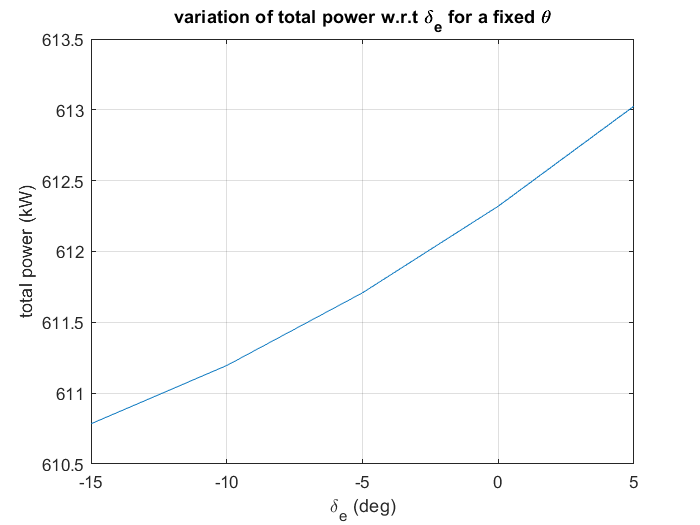


figure(1)
plot(rad2deg(array_delta_e),array_power_total/1000);
xlabel('\delta_e (deg)'); ylabel('total power (kW)'); title('variation of total power w.r.t \delta_e for a fixed \theta'); grid on;

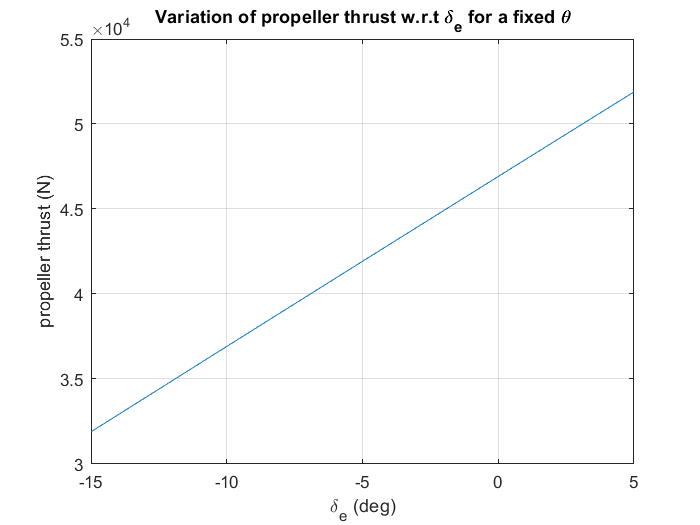

figure(2)
plot(rad2deg(array_delta_e),rad2deg(array_prop_thrust));
xlabel('\delta_e (deg)'); ylabel('propeller thrust (N)'); title('Variation of propeller thrust w.r.t \delta_e for a fixed \theta'); grid on;

## It looks like a negative delta_e can always decrease the power 

but is it really necessary to use the elevator in a low speed? We need to look the control derivative of the elevator, and of theta_1s (to control M)

% first, set the theta to our preconfig value
% we read from trimmed table (with prop) and see the variation of
% dMddelta_e

array_U = 0:5:100;
array_dMddelta_e = zeros(size(array_U));
array_dMdtheta_1s = zeros(size(array_U));

[~,number_of_U] = size(array_U);


for k = 1:number_of_U
    disp(array_U(k))
    [x_trim,Rotorcraft,~] = calculate_from_trim_table(table_trim_redundant_prop(table_trim_redundant_prop.U == array_U(k),:));
    derivatives_primitive = calculate_derivatives_primitive(Rotorcraft,x_trim);
    array_dMddelta_e(k) = derivatives_primitive.dMddelta_e;
    array_dMdtheta_1s(k) = derivatives_primitive.dMdtheta_1s;
end

     0

     5

    10

    15

    20

    25

    30

    35

    40

    45

    50

    55

    60

    65

    70

    75

    80

    85

    90

    95

   100



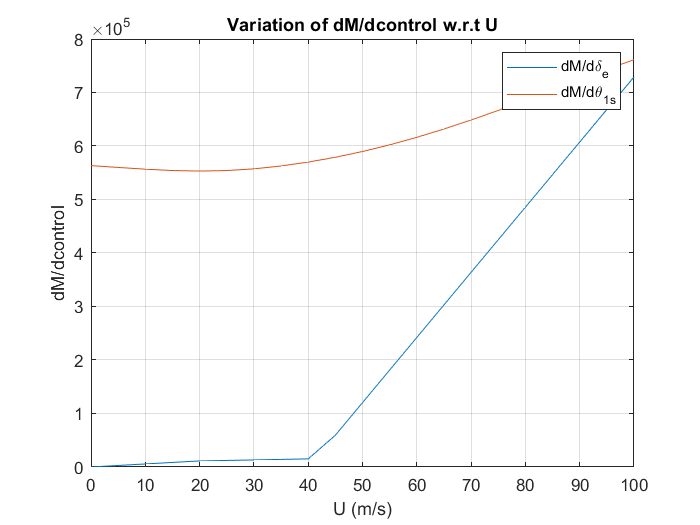


plot(array_U, abs(array_dMddelta_e)); 
hold on
plot(array_U, abs(array_dMdtheta_1s)); 
hold off
legend('dM/d\delta_e','dM/d\theta_{1s}')
xlabel('U (m/s)'); ylabel('dM/dcontrol'); title('Variation of dM/dcontrol w.r.t U');grid on;

## Find the best delta_e to  decrease power

array_U = 90:5:100;
[~,number_of_U] = size(array_U);
best_delta_e = zeros(size(array_U));
best_power = zeros(size(array_U));
for m = 1:number_of_U
    disp(array_U(m))
    
    array_delta_e = linspace(deg2rad(-10),deg2rad(1),40);
    [~, number_of_delta_e] = size(array_delta_e);
    array_prop_thrust = zeros(size(array_delta_e));
    array_power_total = zeros(size(array_delta_e));
    
    table_trim_no_redundant = readtable('trim_result_redundant_prop.csv');
    table_propeller_config = readtable('propeller_config.csv');
    table_theta_preconfig = readtable('theta_preconfig.csv');
    
    Rotorcraft = struct;
    Rotorcraft.DoubleRotorHelicopter    = DoubleRotorHelicopter;
    Rotorcraft.LowerRotor               = LowerRotor;
    Rotorcraft.UpperRotor               = UpperRotor;
    Rotorcraft.Prop                     = Prop;
    Rotorcraft.Fus                      = Fus;
    Rotorcraft.HorStab                  = HorStab;  
    Rotorcraft.VerStab                  = VerStab;
    Rotorcraft.DoubleRotorHelicopter.U         = array_U(m);
    Rotorcraft.DoubleRotorHelicopter.V         = 0;
    Rotorcraft.DoubleRotorHelicopter.W         = 0;
    Rotorcraft.DoubleRotorHelicopter.U_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.V_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.W_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.p         = 0;
    Rotorcraft.DoubleRotorHelicopter.q         = 0;
    Rotorcraft.DoubleRotorHelicopter.r         = 0;
    Rotorcraft.DoubleRotorHelicopter.p_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.q_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.r_dot     = 0;
    
    nearest_initial = table_trim_no_redundant{table_trim_no_redundant.U == fix(Rotorcraft.DoubleRotorHelicopter.U),2:10};
    zero_force_theta_0_prop = table_propeller_config.zeros_force_theta_0(table_propeller_config.U == ceil(Rotorcraft.DoubleRotorHelicopter.U));
    theta_0_prop_last = zero_force_theta_0_prop+deg2rad(5);
    
    % find the preconfig theta
    theta_specified = table_theta_preconfig.theta_preconfig(table_theta_preconfig.U==Rotorcraft.DoubleRotorHelicopter.U);
    
    for k  = 1:number_of_delta_e
        disp(array_delta_e)
        % find the corresp theta_0_prop
        problem = struct;
        problem.objective   = @(x) (theta_specified-find_theta_given_prop(Rotorcraft, [x, array_delta_e(k), 0], nearest_initial))^2*1e3;
        problem.x0          = theta_0_prop_last;
        problem.lb          = zero_force_theta_0_prop;
        problem.ub          = zero_force_theta_0_prop+deg2rad(25);
        problem.solver      = 'fmincon';
        problem.options     = optimset('Display','iter','Algorithm','sqp');
        theta_0_prop = fmincon(problem);
        
        theta_0_prop_last = theta_0_prop;
    
        % get the trim states
        [theta,x_trim,Rotorcraft,power_total] = find_theta_given_prop(Rotorcraft,[theta_0_prop, array_delta_e(k), 0], nearest_initial_no_redundant);
    
        % record 
        array_prop_thrust(k)   = Rotorcraft.Prop.T_blade_element;
        array_power_total(k)    = power_total;
    end
end

    90



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2    1.472426e+01     0.000e+00     1.000e+00     0.000e+00     2.126e+02  
    1           4    3.520588e+00     0.000e+00     1.000e+00     8.727e-02     1.339e+02  
    2           6    3.520588e+00     0.000e+00     1.000e+00     0.000e+00     0.000e+00  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the 

## 316 Let's try another strategy (useless)

we vary delta_r also use propeller to satisfy theta, to observe the power variation

% define the variation domain
array_delta_r = linspace(deg2rad(-5),deg2rad(5),5);
[~, number_of_delta_r] = size(array_delta_r);
array_prop_thrust = zeros(size(array_delta_r));
array_power_total = zeros(size(array_delta_r));

for k  = 1:number_of_delta_r
    table_trim_no_redundant = readtable('trim_result_redundant_prop.csv');
    table_propeller_config = readtable('propeller_config.csv');
    table_theta_preconfig = readtable('theta_preconfig.csv');
    
    disp(array_delta_r(k))
    
    Rotorcraft = struct;
    Rotorcraft.DoubleRotorHelicopter    = DoubleRotorHelicopter;
    Rotorcraft.LowerRotor               = LowerRotor;
    Rotorcraft.UpperRotor               = UpperRotor;
    Rotorcraft.Prop                     = Prop;
    Rotorcraft.Fus                      = Fus;
    Rotorcraft.HorStab                  = HorStab;  
    Rotorcraft.VerStab                  = VerStab;
    Rotorcraft.DoubleRotorHelicopter.U         = 80;
    Rotorcraft.DoubleRotorHelicopter.V         = 0;
    Rotorcraft.DoubleRotorHelicopter.W         = 0;
    Rotorcraft.DoubleRotorHelicopter.U_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.V_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.W_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.p         = 0;
    Rotorcraft.DoubleRotorHelicopter.q         = 0;
    Rotorcraft.DoubleRotorHelicopter.r         = 0;
    Rotorcraft.DoubleRotorHelicopter.p_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.q_dot     = 0;
    Rotorcraft.DoubleRotorHelicopter.r_dot     = 0;
    
    nearest_initial_no_redundant = table_trim_no_redundant{table_trim_no_redundant.U == fix(Rotorcraft.DoubleRotorHelicopter.U),2:10};
    zero_force_theta_0_prop = table_propeller_config.zeros_force_theta_0(table_propeller_config.U == ceil(Rotorcraft.DoubleRotorHelicopter.U));

    % find the preconfig theta
    theta_specified = table_theta_preconfig.theta_preconfig(table_theta_preconfig.U==Rotorcraft.DoubleRotorHelicopter.U);

    % find the corresp theta_0_prop
    problem = struct;
    problem.objective   = @(x) (theta_specified-find_theta_given_prop(Rotorcraft, [x, 0, array_delta_r(k)], nearest_initial_no_redundant))^2*1e3;
    problem.x0          = zero_force_theta_0_prop+deg2rad(5);
    problem.lb          = zero_force_theta_0_prop;
    problem.ub          = zero_force_theta_0_prop+deg2rad(25);
    problem.solver      = 'fmincon';
    problem.options     = optimset('Display','iter','Algorithm','sqp');
    theta_0_prop = fmincon(problem);

    % get the trim states
    [theta,x_trim,Rotorcraft,power_total] = find_theta_given_prop(Rotorcraft,[theta_0_prop, 0, array_delta_r(k)], nearest_initial_no_redundant);

    % record 
    array_prop_thrust(k)   = Rotorcraft.Prop.T_blade_element;
    array_power_total(k)    = power_total;
end

figure(1)
plot(rad2deg(array_delta_r),array_power_total);
figure(2)
plot(rad2deg(array_delta_r),rad2deg(array_prop_thrust));

## 316 we are going to reformulate the problem: vary theta_0_prop and delta_e, to see the variation of theta and power (useless)

array_delta_e = linspace(deg2rad(-5),deg2rad(5),5);
[~, number_of_delta_e] = size(array_delta_e);
array_theta_0_prop = linspace(zero_force_theta_0_prop,zero_force_theta_0_prop+deg2rad(25),6);
[~, number_of_theta_0_prop] = size(array_theta_0_prop);
array_prop_thrust = zeros(size(array_delta_e));
array_power_total = zeros(size(array_delta_e));
matrix_power = zeros(number_of_delta_e,number_of_theta_0_prop);
matrix_theta = zeros(number_of_delta_e,number_of_theta_0_prop);

for k = 1:number_of_delta_e
    disp(array_delta_e(k))
    
    for m = 1:number_of_theta_0_prop
        
        table_trim_no_redundant = readtable('trim_result_redundant_prop.csv');
        table_propeller_config = readtable('propeller_config.csv');
        table_theta_preconfig = readtable('theta_preconfig.csv');
    
        Rotorcraft = struct;
        Rotorcraft.DoubleRotorHelicopter    = DoubleRotorHelicopter;
        Rotorcraft.LowerRotor               = LowerRotor;
        Rotorcraft.UpperRotor               = UpperRotor;
        Rotorcraft.Prop                     = Prop;
        Rotorcraft.Fus                      = Fus;
        Rotorcraft.HorStab                  = HorStab;  
        Rotorcraft.VerStab                  = VerStab;
        Rotorcraft.DoubleRotorHelicopter.U         = 80;
        Rotorcraft.DoubleRotorHelicopter.V         = 0;
        Rotorcraft.DoubleRotorHelicopter.W         = 0;
        Rotorcraft.DoubleRotorHelicopter.U_dot     = 0;
        Rotorcraft.DoubleRotorHelicopter.V_dot     = 0;
        Rotorcraft.DoubleRotorHelicopter.W_dot     = 0;
        Rotorcraft.DoubleRotorHelicopter.p         = 0;
        Rotorcraft.DoubleRotorHelicopter.q         = 0;
        Rotorcraft.DoubleRotorHelicopter.r         = 0;
        Rotorcraft.DoubleRotorHelicopter.p_dot     = 0;
        Rotorcraft.DoubleRotorHelicopter.q_dot     = 0;
        Rotorcraft.DoubleRotorHelicopter.r_dot     = 0;
        
        nearest_initial_no_redundant = table_trim_no_redundant{table_trim_no_redundant.U == fix(Rotorcraft.DoubleRotorHelicopter.U),2:10};

        [theta,x_trim,Rotorcraft,power_total] = find_theta_given_prop(Rotorcraft, [array_theta_0_prop(m), array_delta_e(k), 0], nearest_initial_no_redundant);

        matrix_power(k,m) = power_total;
        matrix_theta(k,m) = theta;
        
        figure(1)
        scatter(rad2deg(theta),power_total/1000,'bo'); grid on; xlabel('\theta (deg)');ylabel('power(kW)'); title('\theta vs power');
        hold on
    end
end
hold off

## helper function

function [theta,x_trim,Rotorcraft,power_total] = find_theta_given_prop(Rotorcraft,redundant,nearest_initial_no_redundant)
    % x_trim = [theta_0,theta_diff,theta_1c,theta_1s,theta,phi,v_i1,v_i2,v_iprop]
    % redundant  = [theta_0_prop,delta_e]
    theta_0_prop    = redundant(1);
    delta_e         = redundant(2);
    delta_r         = redundant(3);
    
    options                 = optimset('Display','off','TolFun',1e-15,'Maxiter',30,'Algorithm','levenberg-marquardt' ,'MaxFunEvals',20000);
    cell_InitialStates      = {nearest_initial_no_redundant [0.01,0,0,0,0,0,10,10,1],[0.01,0,0,0,0,0,3,3,1], ...
                                [0.1,0,0,0,0,0,10,10,1],[0.1,0,0,0,0,0,3,3,1], ...
                                [0.2,0,0,0,0,0,10,10,1],[0.2,0,0,0,0,0,3,3,1], ...
                                [0.3,0,0,0,0,0,10,10,1],[0.3,0,0,0,0,0,3,3,1]};
    [x_trim,~,~,~,Rotorcraft,Fnet,power_total] = trim_solve(Rotorcraft, ...
                                    @Aerodynamics_trim_full_9var, ... 
                                    cell_InitialStates, ...
                                    options, ...
                                    2, ...                  % LowerRotor.inteference
                                    2, ...                  % UpperRotor.inteference
                                    theta_0_prop, ...        % Prop.theta_0
                                    1, ...                  % Prop.isEnable
                                    1, ...                  % Fus.isEnable
                                    delta_e, ...         % HorStab.delta_e
                                    1, ...                  % HorStab.isEnable
                                    delta_r, ...         % VerStab.delta_r
                                    1, ...                  % VerStab.isEnable
                                    deg2rad(0), ...         % theta_1c_diff
                                    deg2rad(0));            % theta_1s_diff
     theta = x_trim(5);
end